clear all
clc

instances=strings(12,1);
for i=1:12
    instances(i)="mtVRP"+string(i);
end
timeLimit=[300 300 450 600 450 300 450 450 450 450 600 300]';
LB=[384.48 515.34 515.34 515.34 585.74 585.74 596.49 658.59 658.59 336.44 395.03 395.03]';

## VND

SolVND=cell(12,1);
parfor j=1:12
    instance=instances(j);
    [Best, time, it]=VND(instance,timeLimit(j));
    Best=Objective(Best);
    Best.time=time;
    SolVND{j}=Best;
    disp(instance + "  " + string(it))
end

mtVRP1  34
mtVRP2  43
mtVRP6  33
mtVRP4  69
mtVRP3  75
mtVRP5  70
mtVRP7  98
mtVRP10  40
mtVRP11  49
mtVRP12  71
mtVRP8  85
mtVRP9  89


wrng=[];
for i=1:12
    if ~SolVND{i}.CapF
        wrng=[wrng i];
    end
end
while ~isempty(wrng)
    for i=wrng
        instance=instances(i);
        [Best, time, it]=VND(instance,timeLimit(i));
        Best=Objective(Best);
        Best.time=time;
        SolVND{i}=Best;        
    end
    for i=1:length(wrng)
        if SolVND{wrng(i)}.CapF
            wrng(i)=NaN;
        end
    end
    wrng=wrng(~isnan(wrng));
end
for j=1:12
    Best=SolVND{j};
    Best=Objective(Best);
    Best.SolP=[Best.Sol nan(Best.R,2)];
    for i=1:Best.R
        ind=find(~isnan(Best.SolP(i,:)),1,'last');
        Best.SolP(i,ind+1:ind+2)=[round(Best.ZRoute(i),2) Best.ThF(i)];       
    end
    SolVND{j}=Best;
end
filename="mtVRP_FHenao_VND3.xlsx";    
for i=1:12
    instance=instances(i);
    Best=SolVND{i};
    Range="A"+string(Best.R+1)+":B"+string(Best.R+1);
    writematrix(nan(Best.R+1,100),filename,'Sheet',instance,'AutoFitWidth',false)
    writematrix([Best.SolP],filename,'Sheet',instance,'AutoFitWidth',false)
    writematrix([round(Best.ZDist,2) round(Best.time,2)],filename,'Sheet',instance,'AutoFitWidth',false,'Range',Range)
end        

## Mezcla

SolILS=cell(12,1);
parfor j=1:12
    instance=instances(j);
    [Best, time, it]=MS_ILS_SA(instance,10,3,15,100,10,0.7,timeLimit(j));
    Best=Objective(Best);
    Best.time=time;
    SolILS{j}=Best;
    disp(instance + "  " + string(it))
end

mtVRP1  4853
mtVRP6  1967
mtVRP2  2725
mtVRP3  3688
mtVRP7  1675
mtVRP8  1329
mtVRP5  3095
mtVRP4  4593
mtVRP9  1579
mtVRP10  2441
mtVRP12  2342
mtVRP11  4862


wrng=[];
for i=1:12
    if ~SolILS{i}.CapF
        wrng=[wrng i];
    end
end
while ~isempty(wrng)
    for i=wrng
        instance=instances(i);
        [Best, time, it]=MS_ILS_SA(instance,10,4,10,100,10,0.7,timeLimit(i));
        Best=Objective(Best)
        Best.time=time;
        SolILS{i}=Best;
        disp(instance + "  " + string(it))
    end
    for i=1:length(wrng)
        if SolILS{wrng(i)}.CapF
            wrng(i)=NaN;
        end
    end
    wrng=wrng(~isnan(wrng));
end
for j=1:12
    Best=SolILS{j};
    Best=fixRoute(Best);
    Best.SolP=[Best.Sol nan(Best.R,2)];
    for i=1:Best.R
        ind=find(~isnan(Best.SolP(i,:)),1,'last');
        Best.SolP(i,ind+1:ind+2)=[round(Best.ZRoute(i),2) Best.ThF(i)];       
    end
    SolILS{j}=Best;
end
filename="mtVRP_FHenao_MS_ILS_SA.xlsx";    
for i=1:12
    instance=instances(i);
    Best=SolILS{i};
    Range="A"+string(Best.R+1)+":B"+string(Best.R+1);
    writematrix(nan(Best.R+1,100),filename,'Sheet',instance,'AutoFitWidth',false)
    writematrix([Best.SolP],filename,'Sheet',instance,'AutoFitWidth',false)
    writematrix([round(Best.ZDist,2) round(Best.time,2)],filename,'Sheet',instance,'AutoFitWidth',false,'Range',Range)
end

**Distintos parametros**

nsol=5:10:15;
nPert=3:4:7;
To=75:50:125;
comb=zeros(8,3);
for i=1:2
    comb(4*(i-1)+1:4*i,1)=nsol(i)*ones(4,1);
    for j=1:4
        k=mod(j-1,2)+1;
        comb(2*(j-1)+1:2*j,2)=nPert(k)*ones(2,1);
    end
    for j=1:8
        k=mod(j-1,2)+1;
        comb(j,3)=To(k);
    end
end
names={'# Soluciones', '# Nodos Perturbados', 'Temperatura Inicial'};
tab=array2table(comb,'VariableNames',names);
disp(tab)

    # Soluciones    # Nodos Perturbados    Temperatura Inicial
    ____________    ___________________    ___________________

          5                  3                      75        
          5                  3                     125        
          5                  7                      75        
          5                  7                     125        
         15                  3                      75        
         15                  3                     125        
         15                  7                      75        
         15                  7                     125        



Slts=cell(cell(9,1));
Slts{1}=SolILS;
for k=1:8
    SolILSP=cell(12,1);
    nsol=comb(k,1);
    nPert=comb(k,2);
    To=comb(k,3);
    parfor j=1:12
        instance=instances(j);
        [Best, time, it]=MS_ILS_SA(instance,nsol,nPert,10,To,10,0.7,timeLimit(j));
        Best=Objective(Best);
        Best.time=time;
        SolILSP{j}=Best;
        disp(instance + "  " + string(it))
    end


    wrng=[];
    for i=1:12
        if ~SolILSP{i}.CapF
            wrng=[wrng i];
        end
    end
    while ~isempty(wrng)
        parfor i=wrng
            instance=instances(i);
            [Best, time, it]=MS_ILS_SA(instance,nsol,nPert,10,To,10,0.7,timeLimit(i));
            Best=Objective(Best)
            Best.time=time;
            SolILSP{i}=Best;
            disp(instance + "  " + string(it))
        end
        for i=1:length(wrng)
            if SolILSP{wrng(i)}.CapF
                wrng(i)=NaN;
            end
        end
        wrng=wrng(~isnan(wrng));
    end

    for j=1:12
        Best=SolILSP{j};
        Best=fixRoute(Best);
        Best.SolP=[Best.Sol nan(Best.R,2)];
        for i=1:Best.R
            ind=find(~isnan(Best.SolP(i,:)),1,'last');
            Best.SolP(i,ind+1:ind+2)=[round(Best.ZRoute(i),2) Best.ThF(i)];       
        end
        SolILSP{j}=Best;
    end
    Slts{k+1}=SolILSP;

    filename="mtVRP_FHenao_MS_ILS_SA"+string(k)+".xlsx";    
    for i=1:12
        instance=instances(i);
        Best=SolILSP{i};
        Range="A"+string(Best.R+1)+":B"+string(Best.R+1);
        writematrix(nan(Best.R+1,100),filename,'Sheet',instance,'AutoFitWidth',false)
        writematrix([Best.SolP],filename,'Sheet',instance,'AutoFitWidth',false)
        writematrix([round(Best.ZDist,2) round(Best.time,2)],filename,'Sheet',instance,'AutoFitWidth',false,'Range',Range)
    end
end

mtVRP1  10010
mtVRP6  4097
mtVRP2  5566
mtVRP3  7468
mtVRP7  3470
mtVRP8  2782
mtVRP5  6240
mtVRP4  9388
mtVRP9  3256
mtVRP10  4900
mtVRP12  4791
mtVRP11  9778
mtVRP1  9957
mtVRP6  4054
mtVRP2  5699
mtVRP3  7500
mtVRP7  3306
mtVRP8  2742
mtVRP5  6244
mtVRP4  9315
mtVRP9  3139
mtVRP10  4921
mtVRP12  4740
mtVRP11  9670
mtVRP1  7385
mtVRP6  3016
mtVRP2  3444
mtVRP3  5225
mtVRP7  2674
mtVRP8  2054
mtVRP5  4659
mtVRP4  6909
mtVRP9  2447
mtVRP10  3592
mtVRP12  3656
mtVRP11  7514
mtVRP1  7368
mtVRP6  3019
mtVRP2  3605
mtVRP3  5330
mtVRP7  2598
mtVRP8  2168
mtVRP5  4619
mtVRP4  6941
mtVRP9  2388
mtVRP10  3464
mtVRP12  3537
mtVRP11  7259
mtVRP1  3273
mtVRP6  1324
mtVRP2  1814
mtVRP3  2455
mtVRP7  1097
mtVRP8  894
mtVRP5  2064
mtVRP4  3058
mtVRP9  1059
mtVRP10  1608
mtVRP12  1587
mtVRP11  3245
mtVRP1  3238
mtVRP6  1295
mtVRP2  1799
mtVRP3  2422
mtVRP7  1066
mtVRP8  875
mtVRP5  2030
mtVRP4  3054
mtVRP9  1048
mtVRP10  1613
mtVRP12  1582
mtVRP11  3199
mtVRP1  2408
mtVRP6  972
mtVRP2  1126
mtVRP3  1

## Rutas

instances=strings(12,1);
for i=1:12
    instances(i)="mtVRP"+string(i);
end
txt=cell(12,1);
path="C:\Users\pipeh\OneDrive\Documents\Eafit\6to semestre\Heuristica\Trabajos\Trabajo2";
for j=1:12
    instance=instances(j);
    txt{j}=importdata(path+"\mtVRP Instances\"+instance+".txt");
end
colors = [0, 0.4470, 0.7410;   % Blue  
    0.6350, 0.0780, 0.1840;   % Red    
    0.4660, 0.6740, 0.1880;   % Green    
    0.4940, 0.1840, 0.5560;   % Purple 
    0.9290, 0.6940, 0.1250;   % Yellow 
    0.6350, 0.4470, 0.1250;   % Brown       
    0.9290, 0.6940, 0.8390    % Pink
    0.5, 0.5, 0.5;   % Gray 
    ];

### VND

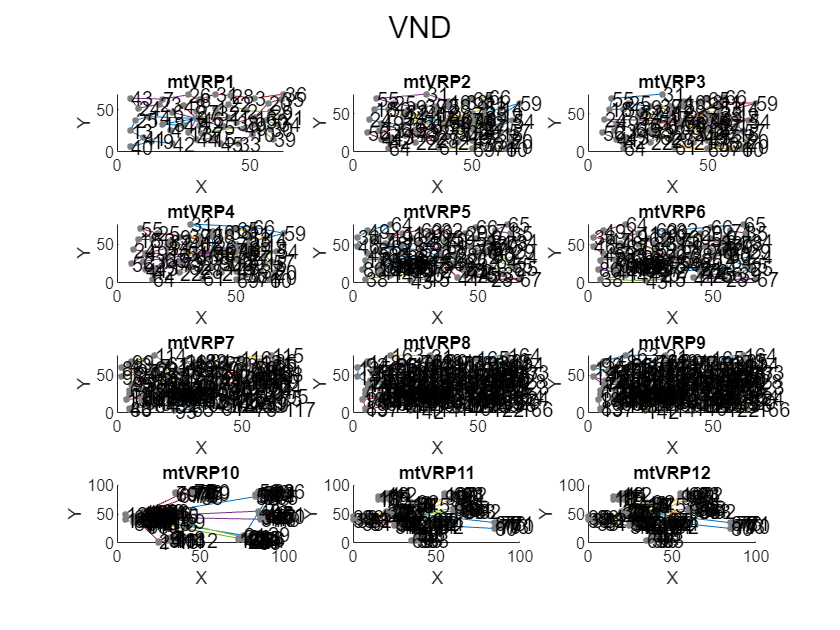

clf
Sol=SolVND;
for k=1:12
    n=txt{k}(1,1);
    X=txt{k}(2:end,2);
    Y=txt{k}(2:end,3);
    nodes=string(0:n);
    subplot(4,3,k)
    hold on
    for i=1:Sol{k}.R
        rt=Sol{k}.Sol(i,:);
        rt=rt(~isnan(rt));
        XRt=X(rt+1);
        YRt=Y(rt+1);
        plot(XRt,YRt,'.-','markersize', 10,'Color',colors(i,:))    
    end
    plot(X,Y,'.','markersize', 10,'Color',colors(end,:)) 
    text(X+0.2,Y,nodes)
    title("mtVRP"+string(k))
    xlabel("X")
    ylabel("Y")
    hold off
end
sgtitle("VND")

### MS_ILS_SA

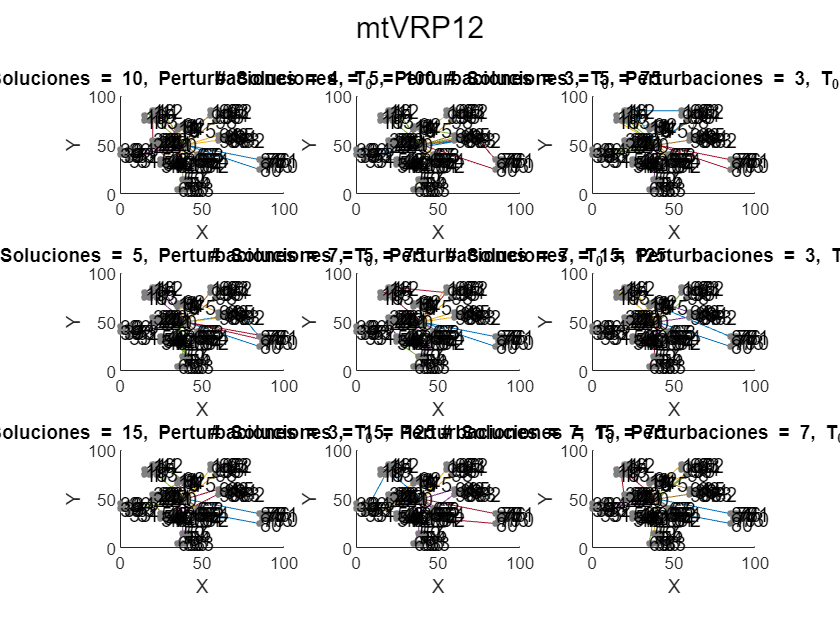

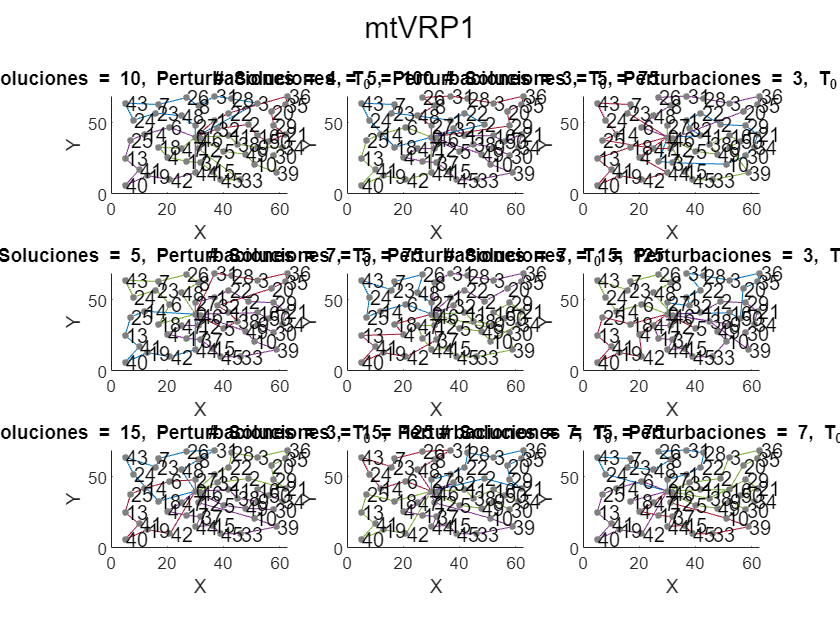

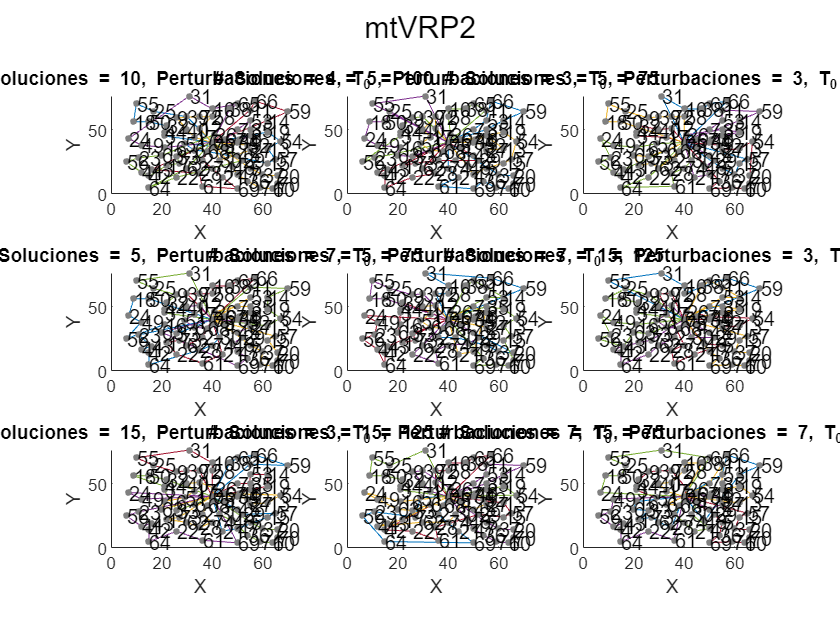

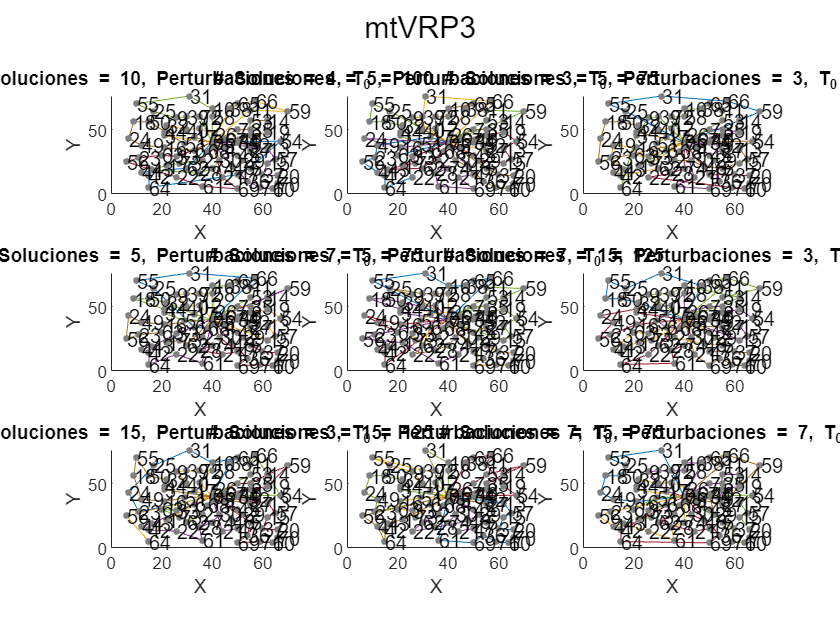

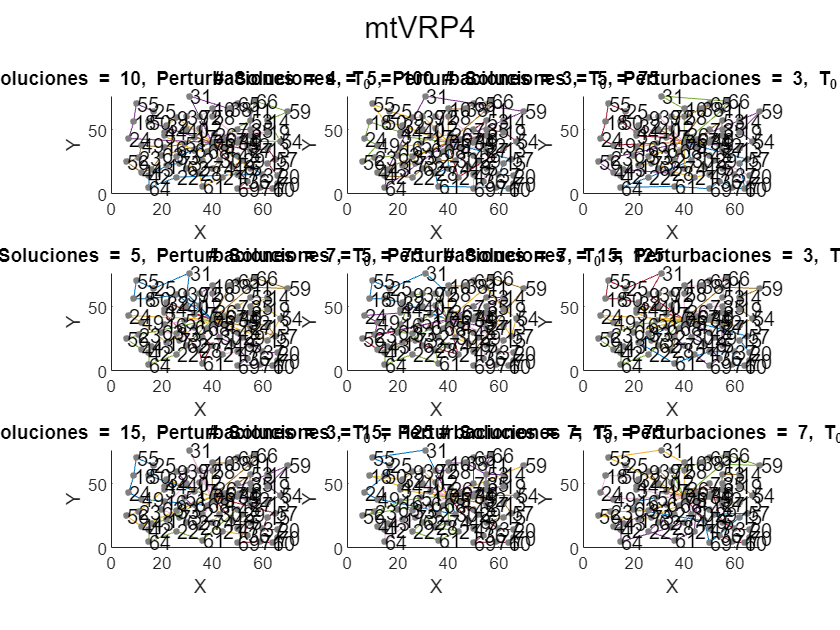

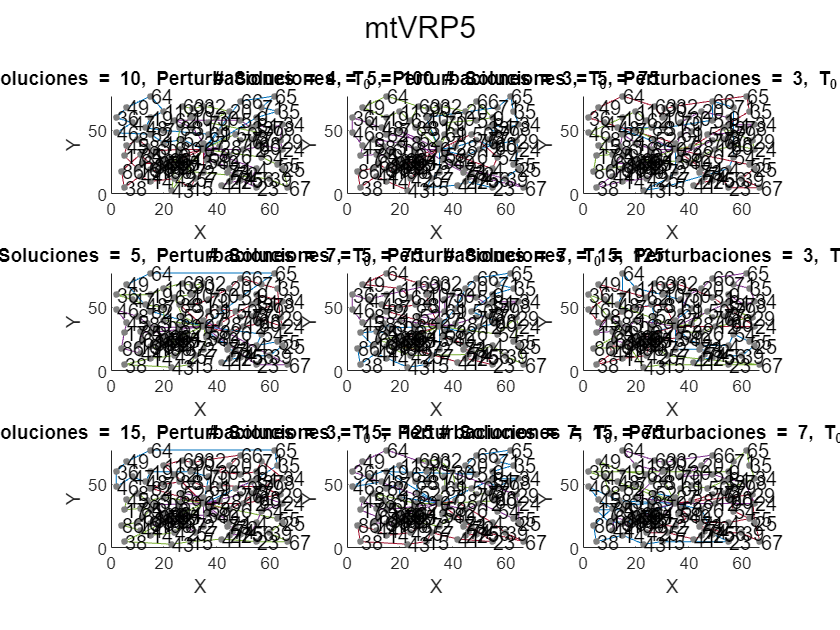

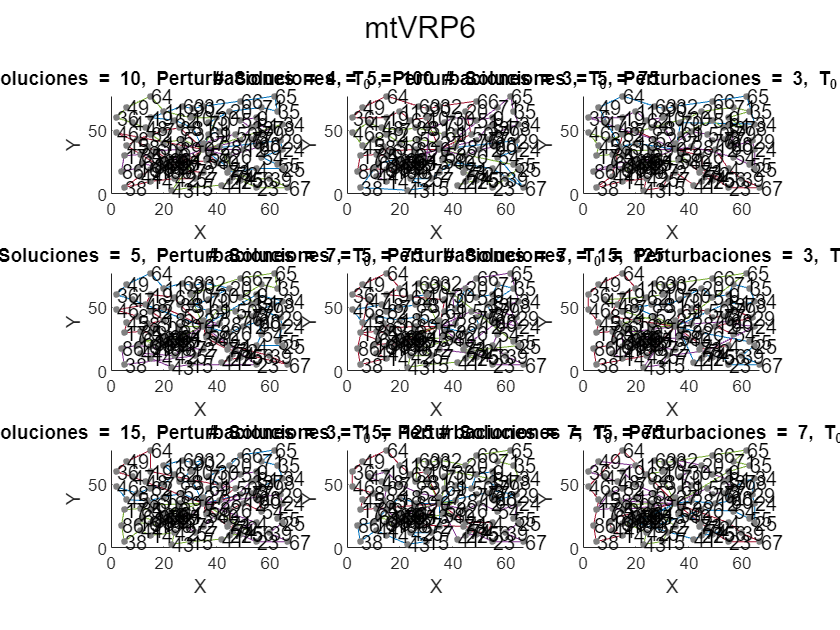

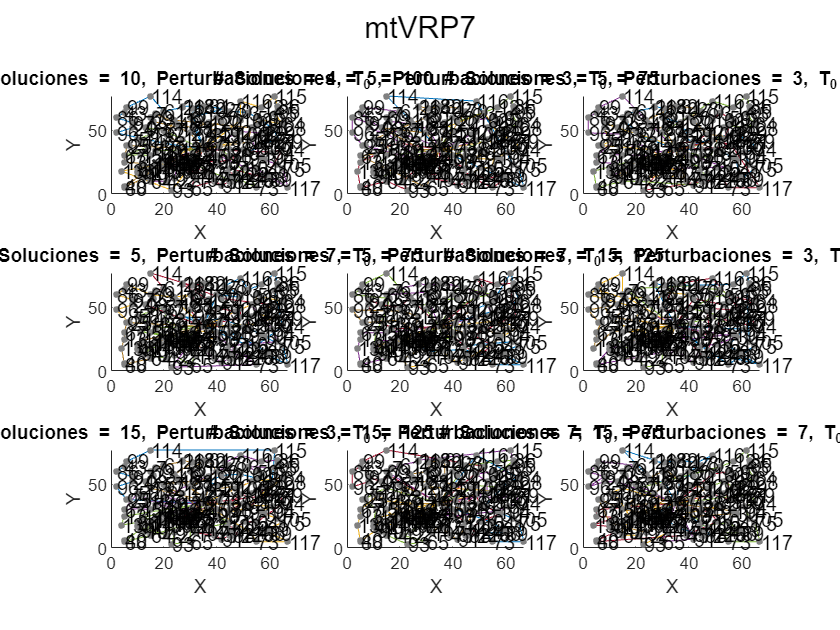

clf
comb=[10 4 100; comb];
for j=1:9
    Sol=Slts{j};
    for k=1:12
        n=txt{k}(1,1);
        X=txt{k}(2:end,2);
        Y=txt{k}(2:end,3);
        nodes=string(0:n);
        figure(k)
        subplot(3,3,j)
        hold on
        for i=1:Sol{k}.R
            rt=Sol{k}.Sol(i,:);
            rt=rt(~isnan(rt));
            XRt=X(rt+1);
            YRt=Y(rt+1);
            plot(XRt,YRt,'.-','markersize', 10,'Color',colors(i,:))    
        end
        plot(X,Y,'.','markersize', 10,'Color',colors(end,:)) 
        text(X+0.2,Y,nodes)
        title("# Soluciones = "+string(comb(j,1))+", Perturbaciones = "+string(comb(j,2))+", T_{0} = "+string(comb(j,3)))
        xlabel("X")
        ylabel("Y")
        hold off
    end    
end
for k=1:12
    figure(k)
    sgtitle("mtVRP"+string(k))
end